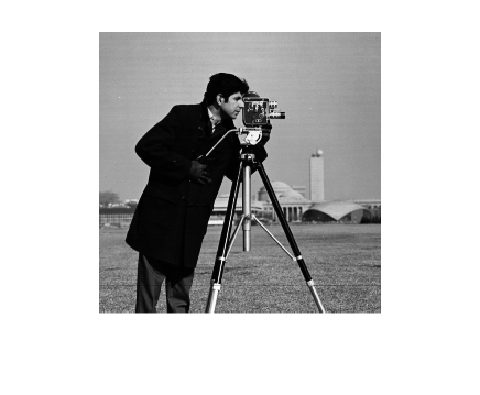

img = im2double(im2gray(imread("cameraman2.tif")));
% Original Image
imshow(img, []); 

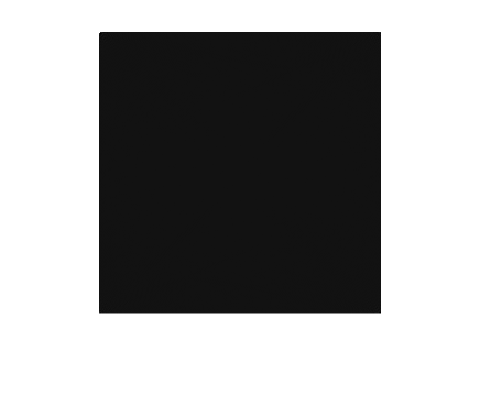

fft = fft2(img);
% Fourier transformed image
imshow(fft,[])

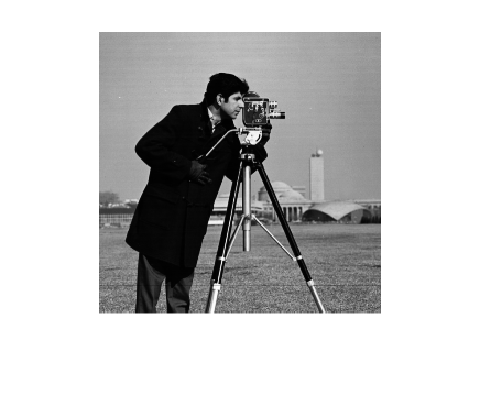

fftimg = ifft2(fft);
% Inverse fourier transform result gives original image
imshow(fftimg,[]);

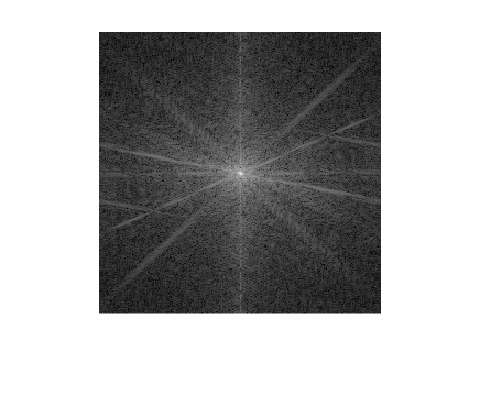

scaledfft = fftshift(log(1 + abs(fft)));
% Scaling fft to see results
imshow(scaledfft,[])

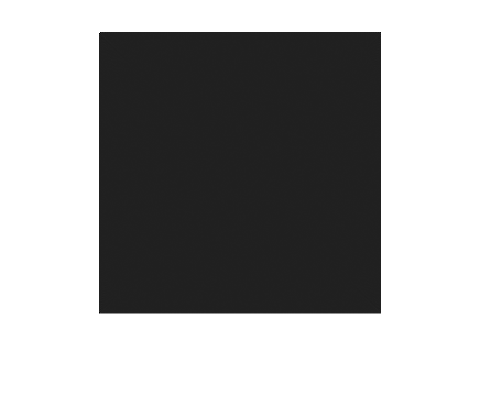

scaledfftimg = ifft2(scaledfft);
% converting scaled fft back to image gives black output
imshow(scaledfftimg,[])